#  Buzz wire Risk Performance Trade-off

This assignment (with two subassignments) is a follow up of the Buzz wire challenge (stochastic version), described in the `buzwirechallenge.mlx` live script and which should be read before starting the present assignment. The way the risk (of hitting the wire) is incorporated in `buzwirechallenge.mlx`  is to have the agent inccur a penalty $CW$when the metal loop hits the wire and terminate the game. However, as acknowledged there, if the metal wire is far from the end goal it might be optimal to hit the wire and incur a penaly $CW$ instead of incurring in a penalty coinciding with the time to reach the end. This behavior does not comply with the usual desired behavior of the Buzz wire challenge. Here a different approach to handle the risk of collision (hitting the wire) is pursued. Namely the two goals, not hitting the wire and reaching the end stage/goal in minimal time, are first separated, and discussed in Sections 1 and 2, respectively. How to combine the two goals is discussed in Section 3 and the assignments are stated in Section 4. 

For concreteness the following parameters (same as in `buzwirechallenge.mlx`) will be used to illustrate the ideas.


clear all
close all
Nx     = 30;
Ny     = 20;
Ntheta = 17;
Mx     = 4;
My     = 5;
Mtheta = 5;
n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;
deltawire = 0.1;
x_ = 1:deltawire:Nx; wirefunction = 10*ones(size(x_))+5*sin(0.2*x_);
p  = [0.04 0.12 0.04 0.12 0.36 0.12 0.04 0.12 0.04];

## 1. Risk of hitting the wire

For a given policy and a given initial state we can exactly compute the probability of hitting the wire. This probability, a number between $0$ and $1$, can be seen as a measure of risk.

In order to compute this probability, we start by denoting the set of configurations $\bar{x}_k = [p_{x,k} \ \ p_{y,k} \ \ \theta_k]^T$ for which the metal loop does not hit the wire by $\mathcal{C}$, i.e., $\bar{x}_k\in \mathcal{C}$ will lead to an output $0$ when the function `metaltoucheswire` is called for such a state. Moreover, we assume that the given policy (assigning a next configuration given the present configuration, see `buzwirechallenge.mlx`) is such that for any set of disturbances the game is over after $T$ steps. We let $E$ be an additional state indicating that the game has ended either because of a collision or because the end goal has been reached and we define the actual state of the system to be


$$$$ x_k = \left\{\matrix{E \text{ if game has ended } \cr \bar{x}_k \text{ otherwise }}\right.$$$$


Then


$$\text{Prob}[x_k \notin \mathcal{C}, \text{ for some }k\in \{1,2,\dots,T\} ]= \mathbb{E}[\sum_{k=1}^T g_R(x_k))]$$


where 


$$$ g_R(x_k) = \left\{\matrix{0 \text{ if } {x}_k =E  \text{or if } x_k=\bar{x}_k \in \mathcal{C} \cr 1 \text{ if }x_k=\bar{x}_k \notin \mathcal{C}}\right. $$$


This probability can then be computed using dynamic programming. To this effect, we can recycle the function `buzzwiredpstoch` in `buzwirechallenge.mlx` that computes and optimal cost, by changing the cost function to coincide with the one above and also setting the cost of actions that do not coincide with the given policy to infinity (this way the given policy is enforced). The function below `buzzwirehitprob`  provides such an implementation. The following script allows to test this function where the given policy is obtained by calling the previous `buzzwiredpstoch` function for different values of $CW$. Note that, for a given initial configuration $\bar{x}_1=[\matrix{1 & 11 & 17}]$, as $CW$ increases, the policy from the given script will be stronger in preventing collisions and thus the probability of collision (risk) will be smaller. If $CW$ is very small then the probability of hitting the wire becomes $1$ for each given state, since the agent will profit from ending the game with a small penalty (one can check that for $CW\leq 11$, `prob1(1,11,17) =1`), which is the issue already mentioned.

CW = 14;
[~,~,mucanonical1] = buzzwiredpstoch(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,CW,p);
[prob1] = buzzwirehitprob(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical1);
prob1(1,11,17) % a given initial configuration is chosen px = 1, py = 11, theta = 17

ans = 0.0597

CW = 17;
[~,~,mucanonical2] = buzzwiredpstoch(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,CW,p);
[prob2] = buzzwirehitprob(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical2);
prob2(1,11,17)

ans = 0.0313

## 2. Expected time to reach the goal

Suppose that we are now interested in assessing the performance of a policy by the expected time of reaching the end goal given that no collision has happened, so by not taking into account the risk of collision. In other words, for each initial configuration, from all the trajectories of the system (determined by the disturbances once the policy is fixed) that do reach the end goal, what is their expected length (time). Given an initial condition, the percentage of such trajectories will be $100\times(1-p)$ where $p$ is the probability of hitting the wire as computed above. In mathematical terms, and again assuming that a given policy is available such that for any set of disturbances the game is over after $T$ steps we wish to compute


$$\mathbb{E}[\sum_{k=1}^T g_E(x_k))|x_k \in \mathcal{C} \text{ or } x_k = E]$$


where 


$$$$ g_E(x_k) = \left\{\matrix{0 \text{ if } {x}_k =E \cr 1 \text{ otherwise}}\right. $$$$


It is still possible to compute this cost for a given policy, by defining a related (but different!) process/model where the probabilities are modified for each state so that disturbances that lead to a collision have zero probability. This is only needed for configuration states for which, for the given policy and for a given state, there is at least one possible disturbance that leads to a collision. Recall that according to the stochastic model, for a given state and corresponding action (since the policy is given), there are $n_w=9$ possible state outcomes (corresponding to $n_w$ disturbances) with probabilities $$$p = [p_1 \, p_2 \, p_3 \,\dots p_9]$$$. For a given state $x_k$ let $K_1$ denote the indices of disturbances that lead to colisions and $\mathcal{K_2}$ the indices that do not lead to collisions, so that $K_1 \cup K_2 = \{1,2,\dots,9\}$and $K_1\cap K_2 = \emptyset$. Then the probability distribution for that state changes from $p$ to $\bar{p}$ with 


$$$\bar{p}_i= \left\{ \matrix{\frac{ p_i}{\alpha}\text{ if }i \in K_2, \cr 0 \text{ if }i \in K_1,}\right. \ \ \ \ \ \alpha = \sum_{i\in K_2}p_i$$$


These sets $K_1$ and $K_2$ and probability distributions $\bar{p}$ depend on the state $x_k$ but the dependence is here omitted.  For instance, suppose that $p= [\matrix{0.1 & 0.1 & 0.1 & 0.2 & 0.2 & 0.1 & 0.1 & 0.1 & 0}]$ and outcomes 3 and 5 lead to a colliision for a given state($$K_1=\{3,5\}$$, $K_2=\{1,2,4,6,7,8,9\}$ ), then the probability distribution of the disturbances is changed to $\bar{p}= [\matrix{0.1 & 0.1 & 0 & 0.2 & 0 & 0.1 & 0.1 & 0.1 & 0}]/0.7$. For this new model/process the cost is simply given by 


$$$$ \mathbb{E}[\sum_{k=1}^T g_E(x_k))]$$$$


which is in the usual form.

The implementation is given in the matlab function `buzzwirenoriskexpectedtime` below. It can be tested as follows (run first previous section). Note that indeed as the risk increases the expected time decreases (so more risky policies will lead to better time, there is a trade-off)

% CW = 14;
[expectedtime1] = buzzwirenoriskexpectedtime(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical1);
expectedtime1(1,11,17)

ans = 12.2427

% CW = 17;
[expectedtime2] = buzzwirenoriskexpectedtime(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical2);
expectedtime2(1,11,17)

ans = 12.5222

## 3. Combining the two goals

Running the instructions above for different values of CW will allow one to understand the trade-off by ploting the risk versus the expected time. By running the following instructions such a plot is generated. The plot also shows the curve $\alpha$ risk + expectedtimes = $\delta$ for $\alpha$=100, where $\delta=13.49$ is the smallest value showing that if we want to minimize this quantity ($\alpha$ risk + expectedtimes) the best point corresponds to $CW=21$.

% values obtained with C = [   12     13     14      15     16         17     18       19     20     21]
risks  =                   [ 0.1821  0.0710  0.0597  0.0446  0.0323  0.0313   0.0313  0.0262  0.0066   0.0066];
expectedtimes =            [ 11.6702 12.1418 12.2427 12.4106 12.5173 12.5222  12.5222 12.6079 12.8354  12.8354];
alpha = 100;
delta = min(alpha*risks+expectedtimes)

delta = 13.4954

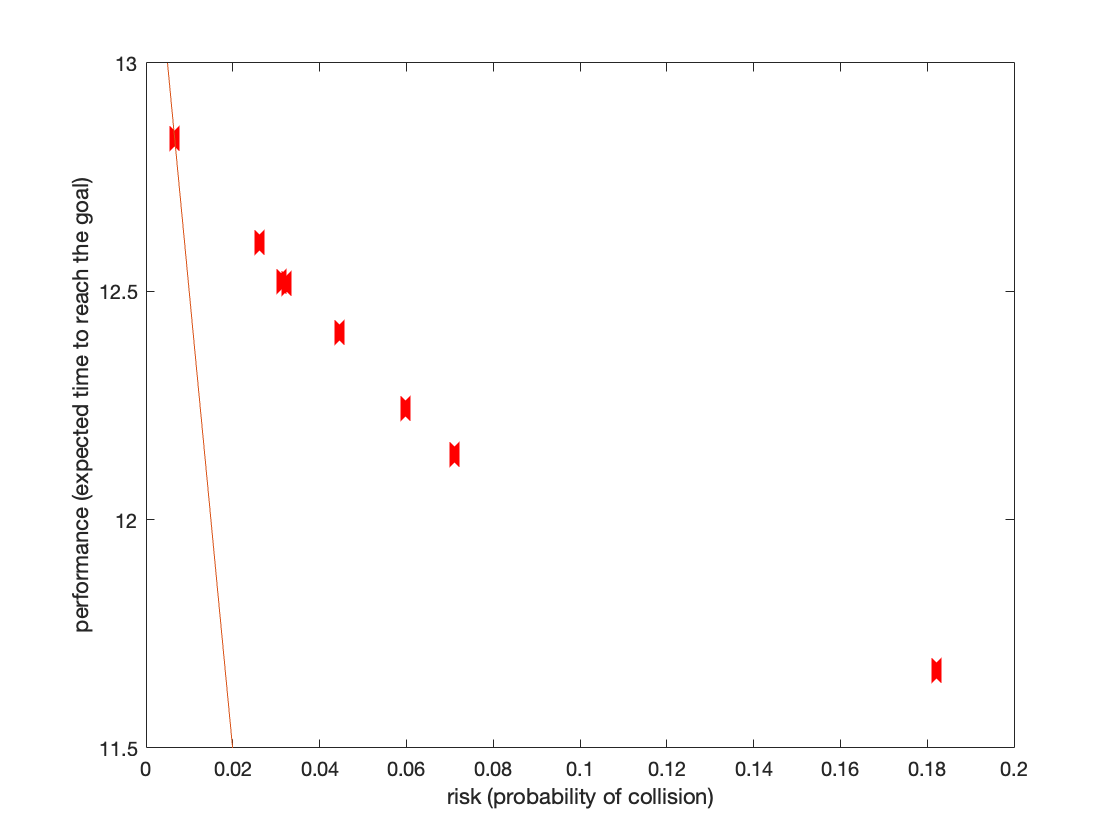

riskx = 0:0.001:0.2;
plot(risks,expectedtimes,'rx','LineWidth',20)
hold on
plot(riskx,delta-alpha*riskx)
axis([0 0.2 11.5 13])
xlabel('risk (probability of collision)')
ylabel('performance (expected time to reach the goal)')

We could conceivably compute the risk and expected time for all possible policies, obtain a cloud of points in this plot, and obtain the so-called pareto curve that would contain only the policies on the lower fringe of this cloud. This fringe (set of policies) contain optimal policies (with different trade-offs) in the sense that no other policy is simultaneously better in terms of their risk and expected time. This would of course not be feasible since there are many possible policies.

To compute such optimal policies we could use dynamic programming. In fact, it would be possible to find an optimal policy that would combine the two goals, but this would require somewhat advanced knowledge. The main issue is that both goals are defined for two different processes: the original one with probabilities $p$, and the one with modified probabilities $\bar{p}$. 

Therefore we propose to approximate the risk by a quantiy that can be computed with the new model/process with modified probabilities $\bar{p}$ (assignment 1, below).

## **4. Assignments**

**4.1. Assignment 1 - compute modified version of risk**

In this assignment you are asked to compute a quantity that is related and has a similar value to the probability of collision discussed above but can be computed by considering the modified model considered above (with probabilities of disturbances $\bar{p$ instead of $p$). To this effect we will consider that after each collision the game still continues as follows. If the agent was at time $k$ at a state configuration where the metal loop does not hit the wire $x_k \in \mathcal{C}$ and at time $k+1$ at a configuration where it does hit $x_{k+1}^ -\notin \mathcal{C}$ then it instantaneously jumps to a position $x_{k+1} \in \mathcal{C}$ that it would have reached if the random disturbance realization would had been $\bar{p}$. The upperscript $x^-_{k+1}$ indicates that this is the value of $x_{k+1}$ just before the jump, and the actual value at time $k+1$ is $x_{k+1} \in \mathcal{C}$. In other words the new position at time $k+1$ can always be computed by the probability distribution $\bar{p}$. The difference here relies in the cost: if there is a collision (just before time $k+1$) a cost equal to $$1$$ is paid otherwise the cost is zero. The overall desired cost is then the expected number of collisions until the goal is reached. Mathematically, this cost for a given policy such that for any set of disturbances the game is over after $T$ steps is


$$$$ \mathbb{E}[\sum_{k=1}^T g_M(x_k,\beta_k))]$$$$


where 


$$$$ g_M(x_k,\beta_k) = \left\{\matrix{0 \text{ otherwise } \cr 1 \text{ if }\beta_k=1}\right. $$$$


where $\beta_k$ is a bernoulli random variable with $\text{prob}[\beta_k=1]=\text{prob}[x_{k+1}^- \in \mathcal{C}]=\gamma$ and $\text{prob}[\beta=0]=\text{prob}[x_{k+1}^- \notin \mathcal{C}]=1-\gamma$

The assignment is then to provide a function

`[expnumhits] = buzzwiremexpnumberhits(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical)`

with the same parameters as the previous functions that now computes the expected number of collisions until the goal is reached with the same output format as the previous functions. Namely,

The input arguments  `Nx, Ny, Nθ`,  are the size of the set of state components x, y and $\theta$, respectively, and `Mx, My, Mθ `are the size of the set of control input components ux, uy, uthet, `wirefunction +  `is a function which is a row vector with dimensions `Nx−1 +1 `where `δ = 0.1`, with wirefunction(i) =$$f((i-1)\delta+1)$$ (see live script `BuzwireChallenge.mlx` for definition of $f$). The last input parameter is a given policy with

- a cell array mu{r} where $r \in \{1,\dots,Nx\times Ny \times N_\theta \}$ is such that r= `coord2state(ix,iy,itheta,Ny,Ntheta) `with px∈ {1,...,Nx}, py∈ {1,...,Ny}, and itheta∈ {1,...,$$N_\theta$$}, such that θ = {−$$\frac{\pi}{2}$$ + itheta $\frac{\pi}{N_\theta+1}$} where each entry is a vector of indices of optimal decisions. Each index, denoted here by $\ell$ is such that $\ell$ =  `coord2action(jx,jy,jtheta,My,Mtheta)`where `jx,jy,jtheta` index the decision $[\matrix{u_x & u_y & u_\theta}]=[\matrix{jx-1,jy-\frac{My-1}{2}-1,\text{jtheta}-(\text{Mtheta}-1)/2-1}]$ for state [px,py,θ];  use mu{r}(1) as the given policy.

The output argument is:

- a cost-to-go multidimensional vector `expnumhits`(px,py,itheta) where px,py,itheta take values in the sets mentioned above. The cost-to-go is the expected number of hist (cost above) if the game starts at state [px,py,θ]; . For infeasible cases J(px,py,itheta)=∞ and mu{px}{py}{itheta} can take any value. A state is feasible if the wire lies inside the area encompassed by the two blue bars and there is no collision. 

 The outputs expnumhits(1,11,17) are compared next with the original hit probability.

% values obtained with CW = [   12     13     14      15     16         17     18       19     20     21]
risks      =                   [ 0.1821  0.0710  0.0597  0.0446  0.0323  0.0313   0.0313  0.0262  0.0066   0.0066];
expnumhits =                  [0.1977    0.0730  0.0610  0.0453  0.0325  0.0314   0.0314  0.0262   0.0066 0.0066];
CW = 19;
[~,~,mucanonical1] = buzzwiredpstoch(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,CW,p);
%[expnumhits] = buzzwiremexpnumberhits(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical1);
%expnumhits(1,11,17)
% 

**4.2. Assignment 2 - compute optimal policy taking into account the tradeoff risk versus expected time to reach goal**

The assignment consists of providing the optimal policy that minimizes the following cost


$$$ \mathbb{E}[\sum_{k=1}^T \alpha g_M(x_k,\beta_k))+ g_E(x_k,\beta_k))]$$$


where $\alpha$ is an arbitrary constant. To this effect, provide a function

`[cost] = buzzwireopttradeoff(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,alpha)`

with the same input parameters as before and additionally the constant $\alpha$ that now computes this cost with the same output format as the previous function but where now:    

- `cost `is a cost-to-go multidimensional vector `cost`(px,py,itheta) where px,py,itheta take values in the sets mentioned above, and represents the cost above if the game starts at state [px,py,θ]; . For infeasible cases J(px,py,itheta)=∞ and mu{px}{py}{itheta} can take any value. A state is feasible if the wire lies inside the area encompassed by the two blue bars and there is no collision. 

 The optimal policy for this example gives a cost of 12.9782.

alpha = 100;
% [cost] = buzzwireopttradeoff(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,alpha)
% cost(1,11,17)% 12.9782

## **Appendix**

The following function solves the buzz wire problem with uncertainty with stochastic dynamic programming.

function [mu,J,mucanonical] = buzzwiredpstoch(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,CW,p,flag)
if nargin == 9
    flag = 0;
end

np = length(p);
pcases = [-1 1;
    0 1;
    1 1;
    -1 0;
    0 0;
    1 0;
    -1 -1;
    0 -1;
    1 -1];
n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;
D  = zeros(n+1,m,np);
C  = zeros(n+1,m);
Jh      = inf*ones(n+1,1);
Jh(n+1) = 0;

for i = 1:n
    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
    % terminal cost
    if ix == Nx
        if ~metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            Jh(i) = 0;
            C(i,:) = 0;
            D(i,:,:) = n+1;
        else
            Jh(i) = inf;
            C(i,:) = inf;
            D(i,:,:) = n+1;
        end
    else
        if metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            C(i,:)   = CW;
            D(i,:,:) = n+1;
        else
            for j = 1:m
                C(i,j)    = 1;
                for ell = 1:np
                    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
                    [jx,jy,jtheta] = action2coord(j,My,Mtheta);
                    ix_1       = min(max(ix+(jx-1)+pcases(ell,1),1),Nx);
                    iy_1       = min(max(iy+jy-(My-1)/2-1+pcases(ell,2),1),Ny);
                    itheta_1   = min(max(itheta+jtheta-(Mtheta-1)/2-1,1),Ntheta);
                    D(i,j,ell) = coord2state(ix_1,iy_1,itheta_1,Ny,Ntheta);
                end
            end
        end
    end
end
D(n+1,:) = n+1;
C(n+1,:) = 0;

[mu_,J_] = dpspstoch( D, C, p, Jh);
mucanonical = mu_;
J  = zeros(Nx,Ny,Ntheta);

for i = 1:n
    [ix,iy,itheta]    = state2coord(i,Ny,Ntheta);
    J(ix,iy,itheta)   = J_(i);
    if flag == 0
        [jx,jy,jtheta]     = action2coord(mu_{i}(1),My,Mtheta);
        mu{ix}{iy}{itheta} = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
    else
        for j = 1:length(mu_{i})
            [jx,jy,jtheta]       = action2coord(mu_{i}(j),My,Mtheta);
            mu{ix}{iy}{itheta}(j,1:3) = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
        end
    end
end

end


Function to compute risk (probability of hitting the wire of a given policy)


function [J] = buzzwirehitprob(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical)


np = length(p);
pcases = [-1 1;
    0 1;
    1 1;
    -1 0;
    0 0;
    1 0;
    -1 -1;
    0 -1;
    1 -1];
n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;
D  = zeros(n+1,m,np);
C  = zeros(n+1,m);
Jh      = inf*ones(n+1,1);
Jh(n+1) = 0;

for i = 1:n
    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
    % terminal cost
    if ix == Nx
        if ~metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            Jh(i) = 0;
            C(i,:) = 0;
            D(i,:,:) = n+1;
        else
            Jh(i) = inf;
            C(i,:) = inf;
            D(i,:,:) = n+1;
        end
    else
        if metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            C(i,:)   = 1;
            D(i,:,:) = n+1;
        else
            for j = 1:m
                if mucanonical{i}(1) == j
                    C(i,j)    = 0;
                else
                    C(i,j)    = inf;
                end
                for ell = 1:np
                    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
                    [jx,jy,jtheta] = action2coord(j,My,Mtheta);
                    ix_1       = min(max(ix+(jx-1)+pcases(ell,1),1),Nx);
                    iy_1       = min(max(iy+jy-(My-1)/2-1+pcases(ell,2),1),Ny);
                    itheta_1   = min(max(itheta+jtheta-(Mtheta-1)/2-1,1),Ntheta);
                    D(i,j,ell) = coord2state(ix_1,iy_1,itheta_1,Ny,Ntheta);
                end
            end
        end
    end
end
D(n+1,:) = n+1;
C(n+1,:) = 0;

[mu_,J_] = dpspstoch( D, C, p, Jh);

J  = zeros(Nx,Ny,Ntheta);

for i = 1:n
    [ix,iy,itheta]    = state2coord(i,Ny,Ntheta);
    J(ix,iy,itheta)   = J_(i);
    [jx,jy,jtheta]     = action2coord(mu_{i}(1),My,Mtheta);
    mu{ix}{iy}{itheta} = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
end

end

This function computes the expectime time to reach the goal of a given policy

function [J] = buzzwirenoriskexpectedtime(Nx,Ny,Ntheta,Mx,My,Mtheta,wirefunction,p,mucanonical)

np = length(p);
pcases = [-1 1;
    0 1;
    1 1;
    -1 0;
    0 0;
    1 0;
    -1 -1;
    0 -1;
    1 -1];
n = Nx*Ny*Ntheta;
m = Mx*My*Mtheta;
D  = zeros(n+1,m,np);
C  = zeros(n+1,m);
Jh      = inf*ones(n+1,1);
Jh(n+1) = 0;

for i = 1:n+1
    for j = 1:m
        p_(i,j,:) = p;
    end
end
for i = 1:n
    [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
    % terminal cost
    if ix == Nx
        if ~metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            Jh(i) = 0;
            C(i,:) = 0;
            D(i,:,:) = n+1;
        else
            Jh(i) = inf;
            C(i,:) = inf;
            D(i,:,:) = n+1;
        end
    else
        if metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
            C(i,:)   = inf; % this value should now not matter
            D(i,:,:) = n+1;
        else
            for j = 1:m
                if mucanonical{i}(1) == j
                    C(i,j)    = 1;
                    for ell = 1:np
                        [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
                        [jx,jy,jtheta] = action2coord(j,My,Mtheta);
                        ix_1       = min(max(ix+(jx-1)+pcases(ell,1),1),Nx);
                        iy_1       = min(max(iy+jy-(My-1)/2-1+pcases(ell,2),1),Ny);
                        itheta_1   = min(max(itheta+jtheta-(Mtheta-1)/2-1,1),Ntheta);
                        D(i,j,ell) = coord2state(ix_1,iy_1,itheta_1,Ny,Ntheta);
                        if metaltoucheswire(ix_1,iy_1,itheta_1,Nx,Ntheta,wirefunction)
                            p_(i,j,ell)  = 0;
                        else
                            p_(i,j,ell) = p(ell);
                        end
                    end
                    p_(i,j,:) = p_(i,j,:)/sum(p_(i,j,:));
                else
                    C(i,j)    = inf;
                    for ell = 1:np
                        [ix,iy,itheta] = state2coord(i,Ny,Ntheta);
                        [jx,jy,jtheta] = action2coord(j,My,Mtheta);
                        ix_1       = min(max(ix+(jx-1)+pcases(ell,1),1),Nx);
                        iy_1       = min(max(iy+jy-(My-1)/2-1+pcases(ell,2),1),Ny);
                        itheta_1   = min(max(itheta+jtheta-(Mtheta-1)/2-1,1),Ntheta);
                        D(i,j,ell) = coord2state(ix_1,iy_1,itheta_1,Ny,Ntheta);
                        p_(i,j,ell) = p(ell);
                    end
                end
            end
        end
    end
end
D(n+1,:) = n+1;
C(n+1,:) = 0;

[mu_,J_] = dpspstoch2( D, C, p_, Jh);

J  = zeros(Nx,Ny,Ntheta);

for i = 1:n
    [ix,iy,itheta]    = state2coord(i,Ny,Ntheta);
    J(ix,iy,itheta)   = J_(i);
    [jx,jy,jtheta]     = action2coord(mu_{i}(1),My,Mtheta);
    mu{ix}{iy}{itheta} = [jx-1,jy-(My-1)/2-1,jtheta-(Mtheta-1)/2-1];
end

end

The following functions are auxiliary function for solving the problems above with stochastic dynamic programming. They differ slightly

-  dpspstoch.m assumes that both the cost in matrix C do not depend on the disturbances and that the probabilities in matrix p do not depend neither on the state nor or the input

- dpspstoch2.m assumes that the cost does not depend on the disturbances but that the probabilities in matrix p do depend on the state and on the input

- dpspstoch3.m assumes that the cost does depend on the disturbances and that the probabilities in matrix p do depend on the state and on the input

function [u_,J_] = dpspstoch(M, C, p, Jh)

[n,m,~]  = size(M);
np     = length(p);
J      = Jh;
J_     = zeros(n,1);

while(1)
    for i = 1:n
        if any(C(i,:) ~=inf)
            caux = zeros(1,m);
            for j=1:m
                caux(j) = 0;
                for l=1:np
                    caux(j) = caux(j) + p(l)*(C(i,j) + J(M(i,j,l)));
                end
            end
            [J_(i)] = min( caux );
        else
            J_(i) = inf;
        end
    end
    if J == J_;
        for i = 1:n
            if any(C(i,:) ~=inf)
                caux = zeros(1,m);
                for j=1:m
                    caux(j) = 0;
                    for l=1:np
                        caux(j) = caux(j) + p(l)*(C(i,j) + J(M(i,j,l)));
                    end
                end
                u_{i}       = find(J_(i) == caux );
            else
                u_{i} = 1;
            end
        end
        break
    else
        J = J_;
    end
end
end


function [u_,J_] = dpspstoch2(M, C, p, Jh)

[n,m,~]  = size(M);
np     = size(p,3);
J      = Jh;
J_     = zeros(n,1);

while(1)
    for i = 1:n
        if any(C(i,:) ~=inf)
            caux = zeros(1,m);
            for j=1:m
                caux(j) = 0;
                for l=1:np
                    if p(i,j,l) ~= 0
                        caux(j) = caux(j) + p(i,j,l)*(C(i,j) + J(M(i,j,l)));
                    end
                end
            end
            [J_(i)] = min( caux );
        else
            J_(i) = inf;
        end
    end
    if J == J_;
        for i = 1:n
            if any(C(i,:) ~=inf)
                caux = zeros(1,m);
                for j=1:m
                    caux(j) = 0;
                    for l=1:np
                        if p(i,j,l) ~= 0
                            caux(j) = caux(j) + p(i,j,l)*(C(i,j) + J(M(i,j,l)));
                        end
                    end
                end
                u_{i}       = find(J_(i) == caux );
            else
                u_{i} = 1;
            end
        end
        break
    else
        J = J_;
    end
end
end

function [u_,J_] = dpspstoch3(M, C, p, Jh)

[n,m,~]  = size(M);
np     = size(p,3);
J      = Jh;
J_     = zeros(n,1);

while(1)
    for i = 1:n
        if any(C(i,:) ~=inf)
            caux = zeros(1,m);
            for j=1:m
                caux(j) = 0;
                for l=1:np
                    if p(i,j,l) ~= 0
                        caux(j) = caux(j) + p(i,j,l)*(C(i,j,l) + J(M(i,j,l)));
                    end
                end
            end
            [J_(i)] = min( caux );
        else
            J_(i) = inf;
        end
    end
    if J == J_;
        for i = 1:n
            if any(C(i,:) ~=inf)
                caux = zeros(1,m);
                for j=1:m
                    caux(j) = 0;
                    for l=1:np
                        if p(i,j,l) ~= 0
                            caux(j) = caux(j) + p(i,j,l)*(C(i,j,l) + J(M(i,j,l)));
                        end
                    end
                end
                u_{i}       = find(J_(i) == caux );
            else
                u_{i} = 1;
            end
        end
        break
    else
        J = J_;
    end
end
end


These are additional auxiliary functions to convert from a 3 dimensional state to a one dimensional index and back both states and actions.

function [ix,iy,itheta] = state2coord(i,Ny,Ntheta)
ix     = floor( (i-1)/(Ny*Ntheta))+1;
iy     = floor((i-1-(ix-1)*(Ny*Ntheta))/Ntheta)+1;
itheta = i-(ix-1)*(Ny*Ntheta)-(iy-1)*Ntheta;
end

function [i] = coord2state(ix,iy,itheta,Ny,Ntheta)
i = (ix-1)*Ny*Ntheta + (iy-1)*Ntheta + itheta;
end

function [jx,jy,jtheta] = action2coord(j,My,Mtheta)
jx     = floor( (j-1)/(My*Mtheta))+1;
jy     = floor((j-1-(jx-1)*(My*Mtheta))/Mtheta)+1;
jtheta = j-(jx-1)*(My*Mtheta)-(jy-1)*Mtheta;
end

function [j] = coord2action(jx,jy,jtheta,My,Mtheta)
j = (jx-1)*My*Mtheta + (jy-1)*Mtheta + jtheta;
end


The following is a key function determining when the metal touches the wire.

function [boolean] = metaltoucheswire(ix,iy,itheta,Nx,Ntheta,wirefunction)
spacingfingers = 4.1;
deltatheta  = pi/(Ntheta+1);
theta       = itheta*deltatheta-pi/2;
deltawire   = (Nx-1)/(length(wirefunction)-1);
xwire       = ix;
ywire       = wirefunction(round((xwire-1)/deltawire)+1);
if abs(ywire-iy)>spacingfingers
    boolean = 1;
else
    % four corners
    R  = [cos(theta) -sin(theta); sin(theta) cos(theta)];
    d  = spacingfingers/2;
    pu1 = [ix; iy] + R*[-d d]';
    pu2 = [ix; iy] + R*[d d]';
    pl1 = [ix; iy] + R*[-d -d]';
    pl2 = [ix; iy] + R*[d -d]';
    if pu2(1) < 1 || pu1(1) > Nx % if the full metal arm is outside of the environemnt possibly the wire is such that it does not touch
        cu = 1;
    else
        indleftlimu  = round(1+(max(min(pu1(1),Nx),1)-1)/deltawire);
        indrightlimu = round(1+(max(min(pu2(1),Nx),1)-1)/deltawire);
        indtestu     = indleftlimu:indrightlimu;
        for i = 1:length(indtestu)
            xwireu(i)   = 1+(indtestu(i)-1)*deltawire;
            ywireu(i)   = wirefunction(indtestu(i));
            ymetalu(i)   = pu1(2)+ (pu2(2)-pu1(2))/(pu2(1)-pu1(1))*(xwireu(i)-pu1(1));
            cu(i)       = ymetalu(i)-ywireu(i) > 0;
        end
    end

    if pl2(1) < 1 || pl1(1) > Nx
        cl = 1;
    else
        indleftliml  = round(1+(max(min(pl1(1),Nx),1)-1)/deltawire);
        indrightliml = round(1+(max(min(pl2(1),Nx),1)-1)/deltawire);
        indtestl     = indleftliml:indrightliml;
        for i = 1:length(indtestl)
            xwirel(i)   = 1+(indtestl(i)-1)*deltawire;
            ywirel(i)   = wirefunction(indtestl(i));
            ymetall(i)   = pl1(2)+ (pl2(2)-pl1(2))/(pl2(1)-pl1(1))*(xwirel(i)-pl1(1));
            cl(i)       = ymetall(i)-ywirel(i) < 0;
        end
    end

    if all(cu == 1) & all(cl == 1)
        boolean = 0;
    else
        boolean = 1;
    end

end

end